clear; clc; close all;
format short eng
% Plot Colors
LUCopper = [147, 86, 14]/255;
LUCopper_Light = [225, 213, 199]/255;
LUBlue = [17, 55, 125]/255;
LUBlue_Light = [197, 204, 221]/255;
Red_Dark = [192, 0, 0]/255;
Red_Light = [235, 200, 197]/255;
pink = [255, 199, 206]/255;

load('E2038.mat');   % Suppose data is in a variable pz
% % % % % % % % % % % % % % % % % % % % % % % 
%  Test Mean-subtraction to remove DC offset/baseline
dataTest1 = p(:,1) - mean(p(1:10,1));
dataTest2 = p(:,2) - mean(p(1:10,2));
dataTest3 = p(:,3) - mean(p(1:10,3));
dataTest4 = p(:,4) - mean(p(1:10,4));
dataTest5 = p(:,5) - mean(p(1:10,5));
dataTest6 = p(:,6) - mean(p(1:10,6));
dataTest7 = p(:,7) - mean(p(1:10,7));
dataTest8 = p(:,8) - mean(p(1:10,8));
dataTest9 = p(:,9) - mean(p(1:10,9));
dataTest10 = p(:,10) - mean(p(1:10,10));
dataTest11= p(:,11) - mean(p(1:10,11));
dataTest12 = p(:,12) - mean(p(1:10,12));
% % % % % % % % % % % % % % % % % % % % 
data = dataTest6;    % Adjust column to your data of interest
Fs = fs;             % Sampling frequency in Hz
t = (0:length(data)-1)'/Fs;

y = data;
%% Step 2: Spectral Analysis (FFT) to Find Dominant Frequencies
N = length(y);
Y = fft(y);
Y = Y(1:N/2+1);

frequencies = Fs*(0:N/2)/N;
power_spectrum = 20*log10(abs(Y)/max(abs(Y))); % Normalized power (dB)

% Detect dominant frequencies
[peak_mags, peak_freqs] = findpeaks(power_spectrum, frequencies, ...
    'MinPeakHeight', -20, 'MinPeakDistance', 10);

% Select the strongest frequency (highest magnitude)
[~, idx] = max(peak_mags);
dominant_freq = peak_freqs(idx);
fprintf('Dominant frequency: %.2f Hz\n', dominant_freq);

Dominant frequency: 256.79 Hz



%% Step 3: Design Adaptive Bandpass Filter Around Dominant Frequency
bandwidth = 10; % Adjust bandwidth around dominant frequency (Hz)
f_low = dominant_freq - bandwidth/2;
f_high = dominant_freq + bandwidth/2;

% Ensure frequencies are valid (0 < f_low < f_high < Fs/2)
f_low = max(f_low, 1); % Avoid 0 Hz (DC)
f_high = min(f_high, Fs/2 - 1); % Avoid Nyquist frequency

% Design Butterworth filter
order = 4;
[b, a] = butter(order, [f_low, f_high]/(Fs/2), 'bandpass');

% Apply zero-phase filtering
y_filtered = filtfilt(b, a, y);

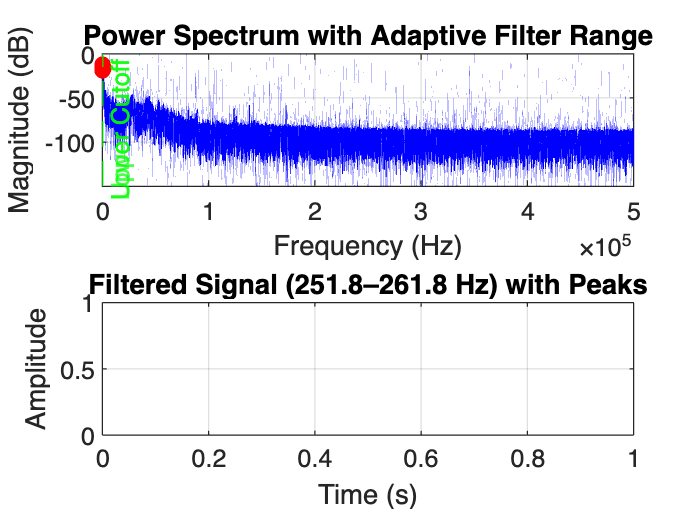


%% Step 4: Detect Peaks in Filtered Signal
[peaks, peak_locations] = findpeaks(y_filtered, t, ...
    'MinPeakProminence', 0.3, 'MinPeakDistance', 0.02);

%% Step 5: Plot Results
% Plot spectrum with dominant frequency
figure;
subplot(2,1,1);
plot(frequencies, power_spectrum, 'b');
hold on;
plot(peak_freqs, peak_mags, 'ro', 'MarkerFaceColor', 'r');
xline([f_low, f_high], '--g', {'Lower Cutoff', 'Upper Cutoff'});
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Power Spectrum with Adaptive Filter Range');
grid on;

% Plot filtered signal and peaks
subplot(2,1,2);
plot(t, y_filtered, 'b');
hold on;
plot(peak_locations, peaks, 'ro', 'MarkerFaceColor', 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title(sprintf('Filtered Signal (%.1f–%.1f Hz) with Peaks', f_low, f_high));
grid on;